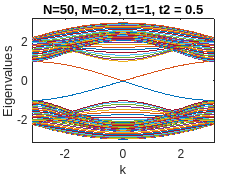

%initializing parameters & Bravais vectors
a1 = 0.5*[-sqrt(3),3];
a2 = 0.5*[sqrt(3),3];
a = 3*norm(a1); %unit cell width


% Define my parameters
t1 = 1;
m = 0;
Ny = 50;
grid = 100;
k_values = -pi/a:pi/grid/a:pi/a;

% convert to alt variables
V=m;
t=t1;
n = Ny; %width in number of atoms
%for L=-0.2:0.01:0.2
N = 2*n; %number of atoms in unit cell

% Define t2 values to loop over
t2_values = linspace(0, 0.5, 100); % Adjust as needed

% Initialize video writer
v = VideoWriter('armchair_bandstructure_haldane.avi', 'Uncompressed AVI');
v.FrameRate = 8; % Adjust the frame rate as needed
open(v);

% Loop over t2 values
for j = 1:length(t2_values)
    L = t2_values(j);
    t2=L;

    % Initialize matrix to store eigenvalues
    Eigenvalues = zeros(N, numel(k_values));
    %Eigenvalues_test = zeros(Ny, numel(k_values));

    % Calculate eigenvalues for each k value
    for g = 1:numel(k_values)

        k = k_values(g);
        u = exp(1i*k*a); %u is phase going right
        
            H_NN  = zeros(N,N);
            H_NNN = zeros(N,N);            
        
        for ii=1:n-1
          %Nearest neighbours
            H_NN(ii,ii+1)     = t;
            H_NN(N-ii+1,N-ii) = t;
            if(mod(ii,2)==0) %even numbers
                H_NN(ii,N-ii+1) = t; %2->13 or for even 2->15
                H_NN(ii,ii) = -V;
            else %odd
                H_NN(ii,N-ii+1) = t*conj(u); %1->14_ or 1->16_
                H_NN(ii,ii) = V;
            end
            
          %Next Nearest Neighbours
            if(ii <= n-2)
                H_NNN(ii,ii+2)       = -((-1)^ii)*1i*L; %1->3
                H_NNN(N-ii+1,N-ii-1) =  ((-1)^ii)*1i*L; %14->12
                H_NNN(ii,N-ii)       =  ((-1)^ii)*1i*L*(1+conj(u)); %1->13,13_
                H_NNN(N-ii+1,ii+1)   = -((-1)^ii)*1i*L*(1+u); %14->2,2+,...if i=1 then +
            end
        end
       %Edge points
        if(mod(n,2)==1) %odd width
            H_NN(n,n+1)    = t*conj(u);
            H_NNN(n-1,n+1) = 1i*L*(1+conj(u));
        else %even width
            H_NN(n,n+1)    = t;
            H_NNN(n-1,n+1) = -1i*L*(1+conj(u));
        end
        
        H = H_NN + H_NNN;
        H = H + H';
        Eigenvalues(:, g) = eig(H);
    end

    % Plotting
    plot(k_values * a, Eigenvalues);
    xlabel('k');
    ylabel('Eigenvalues');
    title(['N=50, M=0.2, t1=1, t2 = ' num2str(t2)]);
    axis([-pi pi -3.2 3.2]);

    % Add frame to video
    frame = getframe(gcf);
    writeVideo(v, frame);
end


% Close video writer
close(v);